%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Solution using Cayley transform and 6-th order implicit Runge-Kutta %
%Methods                                                             %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ButcherTableaux = QGSix;    %Butcher tableaux to be used for RK with Cayley tranform
s = size(ButcherTableaux,2)-1; %number of RK stages
n = 3;                       %size of matrix
h = 0.00001;                    %timestep size
epsilon = 0.00001;             % Distance between iterations of RK method
tInitial = 2.5;
tFinal = 3;                      %final time
ts1 = round(tInitial/h);
ts = round((tFinal-tInitial)/h);               %number of timesteps
v6 = zeros(n,n,s,ts);             %Lie algebra element at time t (matrix,s copies of matrix,timestep number)
y6 = zeros(n,n,ts);               %Lie group element time t
y0 = eye(n);                     %initial condition on Lie group
Knew = zeros(n,n,s);             %RK intermediate stages current result (matrix,stage number)
diff = zeros(1,s);               %Difference between iterations (by stages)
c = zeros(1,ts);                 %Iteration counter
f = waitbar(0);

for t = 1:(ts-1)    %Calculate v for each timestep
 b = true;
 Kold = zeros(n,n,s);
 while b        %Solve nonlinear matrix equation by iteration
   Knew = v6(:,:,:,t) + h*G(Kold,t+ts1-1,h,s,n,ButcherTableaux);
   for i = 1:s
        diff(i) = norm(Knew(:,:,i)-Kold(:,:,i));
   end
   if max(diff) < epsilon
       b = false;
   end
   Kold = Knew;
   c(t) = c(t)+1;
 end
 for m = 1:s
     v6(:,:,m,t+1) = v6(:,:,m,t) + h*C(Knew,t+ts1-1,h,s,n,ButcherTableaux);
 end
 waitbar(t/ts,f);
end
close(f);

for t = 1:ts
    y6(:,:,t) = cay(v6(:,:,1,t),n)*y0;
end



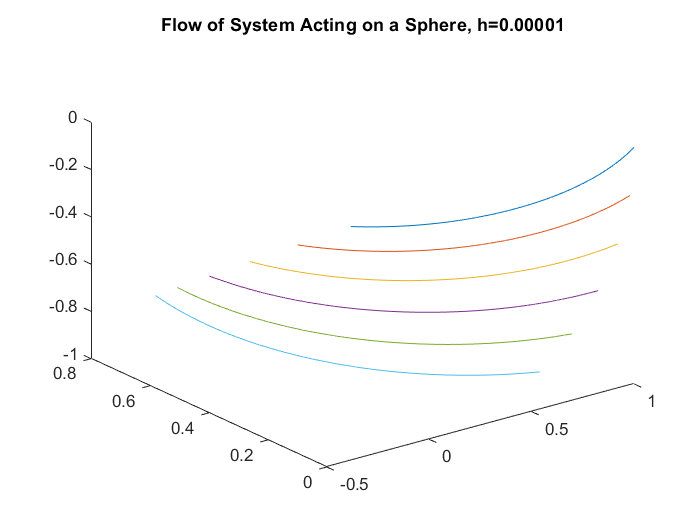

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Act on R3 and graph flow lines for visualization purposes %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

p1 = zeros(3,ts);                %curve on manifold(R3)
p2 = zeros(3,ts);
p3 = zeros(3,ts);
p4 = zeros(3,ts);
p5 = zeros(3,ts);
p6 = zeros(3,ts);
p1i = transpose([1,0,0]);     %Initial condition on manifold  
%establish several initial conditions

p2i = rot1*p1i;
p3i = rot2*p1i;
p4i = rot3*p1i;
p5i = rot4*p1i;
p6i = rot5*p1i;

%solutions to 6th order Lie method act on R3
for t = 1:ts
    p1(:,t) = y6(:,:,t)*p1i; 
end

for t = 1:ts
    p2(:,t) = y6(:,:,t)*p2i;
end

for t = 1:ts
    p3(:,t) = y6(:,:,t)*p3i;
end

for t = 1:ts
    p4(:,t) = y6(:,:,t)*p4i;
end

for t = 1:ts
    p5(:,t) = y6(:,:,t)*p5i;
end

for t = 1:ts
    p6(:,t) = y6(:,:,t)*p6i;
end
%Plot flow curves
plot3(p1(1,:),p1(2,:),p1(3,:),p2(1,:),p2(2,:),p2(3,:),p3(1,:),p3(2,:),p3(3,:),p4(1,:),p4(2,:),p4(3,:),p5(1,:),p5(2,:),p5(3,:),p6(1,:),p6(2,:),p6(3,:))
title('Flow of System Acting on a Sphere, h=0.00001')
saveas(gcf,'D:\Documents\Modelling Project\flow2.jpg')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Solution using Cayley transform and 6-th order implicit Runge-Kutta %
%Methods                                                             %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ButcherTableaux = QGFour;    %Butcher tableaux to be used for RK
s = size(ButcherTableaux,2)-1; %number of RK stages
v4 = zeros(n,n,s,ts);             %Lie algebra element at time t (matrix,s copies of matrix,timestep number)
y4 = zeros(n,n,ts);               %Lie group element time t
Knew = zeros(n,n,s);             %RK intermediate stages current result (matrix,stage number)
diff = zeros(1,s);               %Difference between iterations (by stages)
c = zeros(1,ts);                 %Iteration counter
f = waitbar(0);

for t = 1:(ts-1)    %Calculate v for each timestep
 b = true;
 Kold = zeros(n,n,s);
 while b        %Solve nonlinear matrix equation by iteration
   Knew = v4(:,:,:,t) + h*G(Kold,t+ts1-1,h,s,n,ButcherTableaux);
   for i = 1:s
        diff(i) = norm(Knew(:,:,i)-Kold(:,:,i));
   end
   if max(diff) < epsilon
       b = false;
   end
   Kold = Knew;
   c(t) = c(t)+1;
 end
 for m = 1:s
     v4(:,:,m,t+1) = v4(:,:,m,t) + h*C(Knew,t+ts1-1,h,s,n,ButcherTableaux);
 end
 waitbar(t/ts,f);
end
close(f);

for t = 1:ts
    y4(:,:,t) = cay(v4(:,:,1,t),n)*y0;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 7-th Order non Cayley Approximation for comparison %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
RK = RK7;
YK = zeros(n,n,length(RK));
RKx = zeros(n,n,ts);
L = length(RK);
RKx(:,:,1) = y0;
for t = 1:ts-1
    for i = 1:L
        YK(:,:,i) = RKx(:,:,t)+h*D(YK,t,i,h,n,RK);
    end
    RKx(:,:,t+1) = RKx(:,:,t)+h*E(YK,t,h,n,RK);
end

time = zeros(1,ts);
for t = 1:ts
    time(t) = t*h +2.5;
end

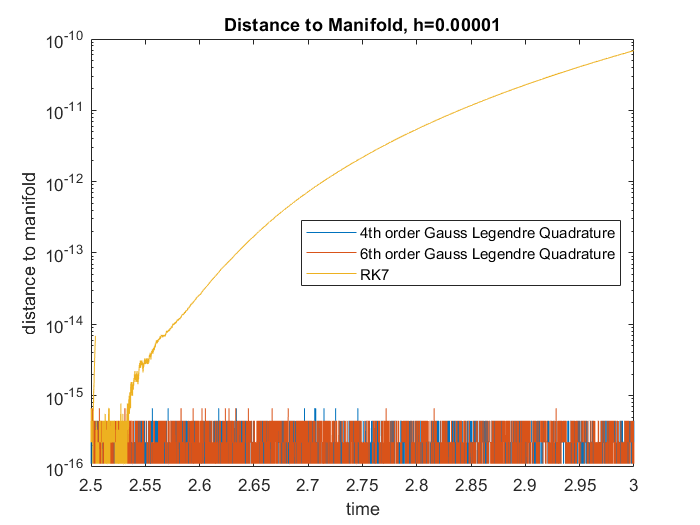

%Distance from manifold
distMan4 = zeros(ts,1);
distMan6 = zeros(ts,1);
distMan7 = zeros(ts,1);
for t = 1:ts
    distMan4(t) = abs(1 - norm(y4(:,:,t)));
    distMan6(t) = abs(1 - norm(y6(:,:,t)));
    distMan7(t) = abs(1 - norm(RKx(:,:,t)));
end
semilogy(time,distMan4,time,distMan6,time,distMan7)
title('Distance to Manifold, h=0.00001')
xlabel('time')
ylabel('distance to manifold')
legend({'4th order Gauss Legendre Quadrature','6th order Gauss Legendre Quadrature','RK7'},'location','east')
saveas(gcf,'D:\Documents\Modelling Project\distance2.jpg')

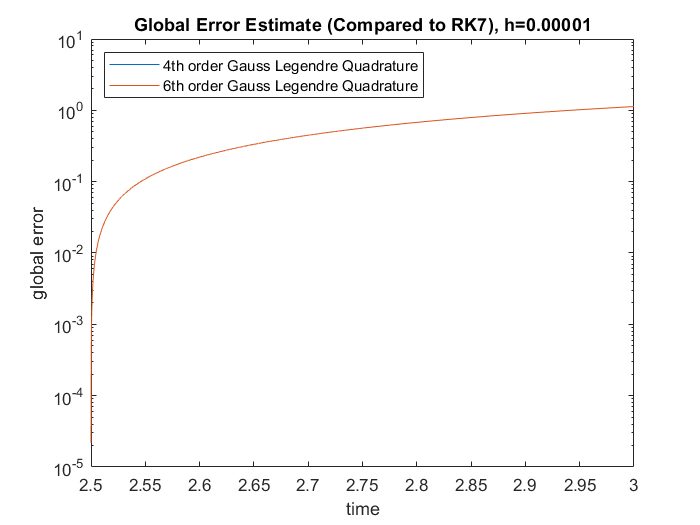

%Error when compared to RK7 solution
error4 = zeros(1,ts);
error6 = zeros(1,ts);
for t = 1:ts
    error4(t) = norm(RKx(:,:,t)-y4(:,:,t));
end
for t = 1:ts
    error6(t) = norm(RKx(:,:,t)-y6(:,:,t));
end

semilogy(time,error4,time,error6)
title('Global Error Estimate (Compared to RK7), h=0.00001')
xlabel('time')
ylabel('global error')
legend({'4th order Gauss Legendre Quadrature','6th order Gauss Legendre Quadrature'},'location','northwest')
saveas(gcf,'D:\Documents\Modelling Project\error2.jpg')

%%%%%%%%%%%%%%%%%%%%%
% Special Functions %
%%%%%%%%%%%%%%%%%%%%%

function v = G(K,t,h,s,n,Butcher)
% Lie RK intermediate steps for timestep t
% input (Matrix (nXn), timestep, timestep size, number of RK stages, matrix size, Butcher Matrix)
v = zeros(n,n,s);
L = length(Butcher);
for i = 1:s
    for k = 1:s
        A = B(t+Butcher(k,L)*h,h,n);
        v(:,:,i) = v(:,:,i) + Butcher(i,k)*(A-(1/2)*(K(:,:,k)*A-A*K(:,:,k))-(1/4)*(K(:,:,k)*A*K(:,:,k)));
    end
end
end

function a = B(t,h,n)%populate A in SO(n)
% input(timestep,timestep size, matrix size)
a=zeros(n);
%populate the matrix A
for l = 1:(n-1)
    for j = (l+1):n
        a(l,j) = (-1)^(l+j)*(l)/(j+1)*(t*h)^(j-l);
    end
end
for l = 1:(n-1)
    for j = (l+1):n
        a(j,l) = (-1)*a(l,j);
    end
end
end

function y = D(yold,t,i,h,n,Butcher)
%Regular RK intermediate step
y = zeros(n);
L = length(Butcher(:,1));
for k = 1:i
    y = y+Butcher(i,k)*B(t+Butcher(k,L)*h,h,n)*yold(:,:,k);
end
end

function x = E(Y,t,h,n,Butcher)
%regular RK final
x = zeros(n);
s = length(Butcher(:,1))-1;
L = length(Butcher(:,1));
for k = 1:s
    x = x + Butcher(L,k)*B(t+Butcher(k,L)*h,h,n)*Y(:,:,k);
end
end

function v = C(K,t,h,s,n,Butcher)
%Lie RK for timestep t
% input (Matrix (nXn), timestep, timestep size, number of RK stages, matrix size, Butcher Matrix)
v = zeros(n);
L = length(Butcher(:,1));
for k = 1:s
    A = B(t+Butcher(k,L)*h,h,n);
    v(:,:) = v(:,:) + Butcher(L,k)*(A-(1/2)*(K(:,:,k)*A-A*K(:,:,k))-(1/4)*(K(:,:,k)*A*K(:,:,k)));
end
end

function c = cay(v,n)
%Cayley transform
c = (eye(n)-(1/2)*v)\(eye(n)+(1/2)*v);
end
